# Guião 4

## Exercicio 1 

% caderno

Ta = 0.001;
t = 0:Ta:1-Ta;
x = 10 + 14*cos(20*pi*t - pi/3) + 8*cos (40*pi*t + pi/2);

fprintf("1.")

1.

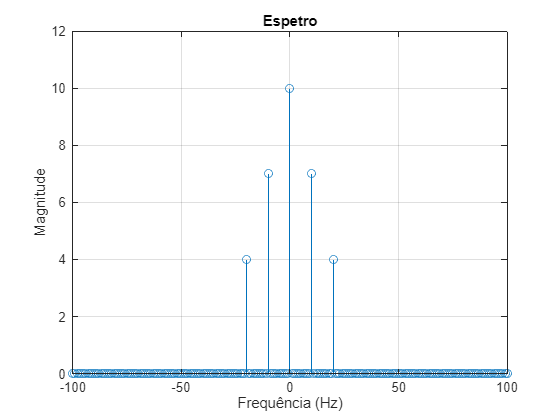

Espetro(x,Ta);
xlim([-100,100])

## Exercicio 2 - Função que mostra o espetro de um sinal

%função em baixo

## Exercicio 3 - Teste da função

% a)
fprintf("2. a)")

2. a)

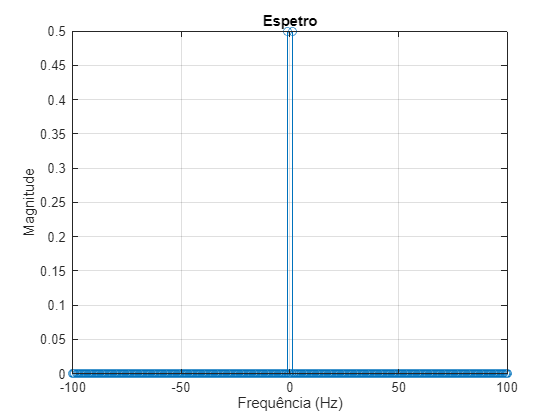


f = 1;
T = 1 / f;

Ta = 0.001;
t = 0:Ta:2*T-Ta;            % 2 periodos = 2 segundos
x = sin(2*pi*t);
Espetro(x,Ta);
xlim([-100,100])


t = 0:Ta : 100-Ta;     % 100 períodos = 100 segundos
Espetro(x,Ta);
xlim([-100,100])


%----------------------------------------------------

% b)
fprintf("2. b)")

2. b)

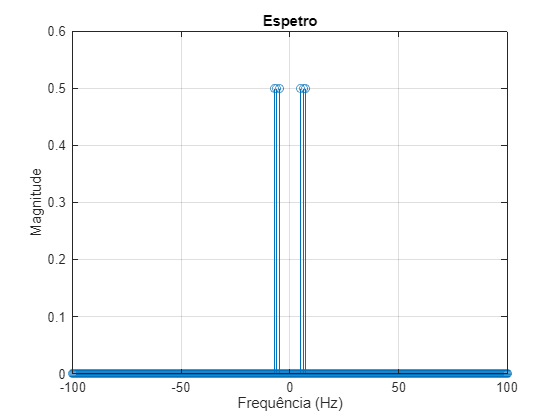


t2 = 0:Ta:50-Ta;
y = sin(10*pi*t2) + cos(12*pi*t2) + cos(14*pi*t2 - pi/4);
Espetro(y,Ta);
xlim([-100,100])


%----------------------------------------------------

% c) igual ao 1

%----------------------------------------------------

% d)
fprintf("2. d)")

2. d)

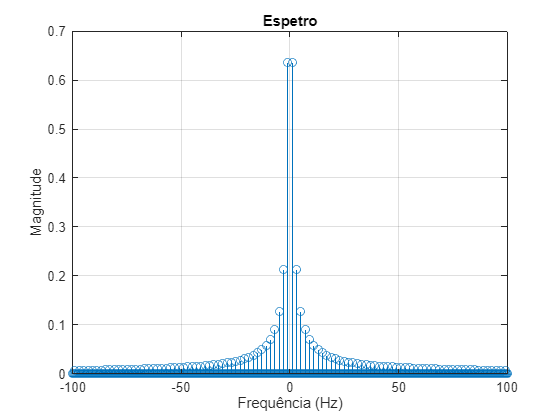


t = 0:Ta:5-Ta;
z = square(2*pi*t);
Espetro(z,Ta);
xlim([-100,100])


%----------------------------------------------------

% e)
fprintf("2. e)")

2. e)

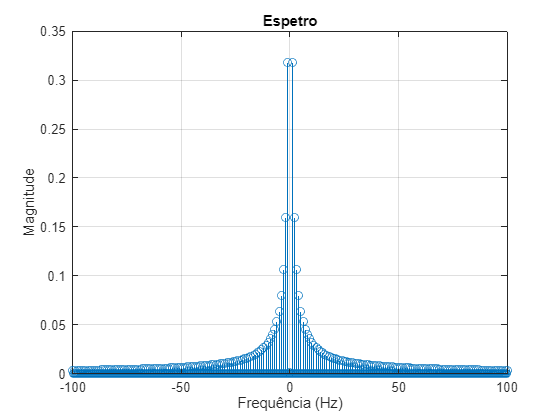


q =  sawtooth(2*pi*t);
Espetro(q,Ta);
xlim([-100,100])

## Exercicio 4 - Função que reconstroi a seq de amostras através do vetor X

% a)
fprintf("4. a)")

4. a)


Ta = 0.001;
t = 0:Ta : 2-Ta;

x = sin(2*pi*t);
[X,f] = Espetro(x,Ta);
xlim([-100,100])

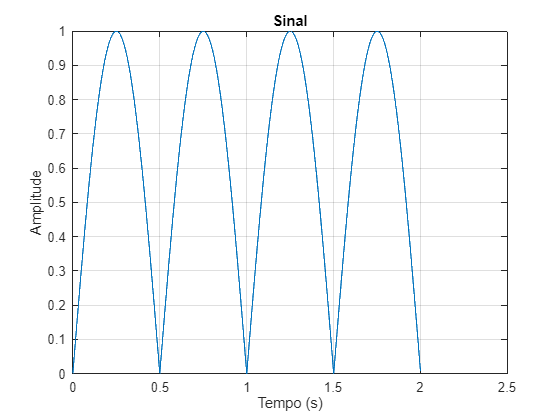

Reconstroi(X,f);


%----------------------------------------------------

% b)
fprintf("4. b)")

4. b)


t2 = 0:Ta:50-Ta;
y = sin(10*pi*t2) + cos(12*pi*t2) + cos(14*pi*t2 - pi/4); 

[X,f] = Espetro(y,Ta);
xlim([-100,100])

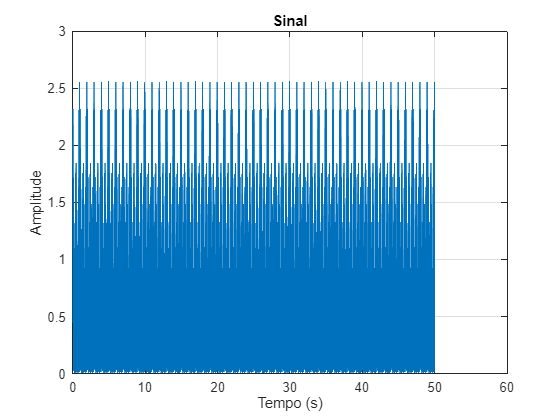

Reconstroi(X,f);

## Funções

function [X, f] = Espetro(x, Ta) 
    % Inputs:
    % x - dimensão do vetor
    % Ta - Periodo de amostragem
    %
    % Outputs:
    % X - vetor da mesma dimensão de x, com coeficientes da dft de x(t)
    % f - vetor da mesma dimensão de x, com as frequências de cada componente
    % de X
    
    Fa = 1 / Ta;                % freq de amostragem
    N = length(x);              % numero de amostras
    
    % fft(x) calcula a dft de x : devolve um
    % vetor complexo que representa amplitude e
    % as fases das componentes das freqs do sinal

    X = fftshift(fft(x))/N;         % fft(x)/N normaliza a dft, para obter amplitude media de cada componente      

    % fftshift reorganiza os valores dos vetores de X para centralizar
    % as frequências em torno de zero

    % resolução frequencia (espaçamento entre amostras de frequência)
    delta_f = Fa / N;
    
    f = (-N/2:N/2-1)*(delta_f);       % vetor de frequencias
    %  cobre o intervalo de -Fa/2 a Fa/2 em passos de delta_f.
                                
                                % abs(x) vai calcular a magnitude de cada
                                % componente
    stem(f, abs(X));            % grafico do tipo haste das magnitudes de em função das frequencias
    xlabel("Frequência (Hz)")
    ylabel("Magnitude")
    title("Espetro")
    grid;

end

function [x,t] = Reconstroi(X,f)
    %   
    %   X : vetor com os coefs da DFT de um sinal no dominio da frequencia
    %   f : vetor com as frequencias correspondentes a cada componente de X
    %
    %   x : vetor com as amostras do sinal reconstruido no dominio do tempo
    %   t : vetor de tempo associado a x

    N = length(X);                      % numero de amostras

    % ifftshift(x) descentraliza o vetor x, ou seja descloca as freqs para
    % a configuração original
    
    % ifft(ifftshift(x)) calcula a transformada inversa de fourier para retornar o sinal do dominio do tempo.
    % ifft toma o vetor de frequencia X e reconstroi o sinal temporal,
    % retorna um vetor complexo

    x = ifft(ifftshift(X))*N;     % multiplica se por N para restaurar a escala original do sinal      
 
    fa = max(f)*2;
    Ta = 1/fa;
    t = (0:N-1)*Ta;

    plot(t,abs(x));
    xlabel("Tempo (s)");
    ylabel("Amplitude");
    title("Sinal")
    grid;
end
